# Ejemplos de robot y cinta trasportadora

Dificultad: Normal (Ejemplos)

clear all
close all


## Introducción

- Se trabaja con un robot y una o más cintas que muevan objetos.

## Robot y cinta trasportadora paralela

- En el fichero *C15S3_Robot_y_Cintas* se define una estación compuesta de una cinta transportadora y un robot Gofa.

- Las articulaciones de la estación son $7$, la primera es un eje prismático de la cinta y las otras $6$ las articulaciones rotacionales del robot Gofa.

- El TCP de la estación puede estar en la cinta, o en la herramienta del robot. En el primer caso se moverá la cinta y en el segundo el robot.

- La cinta mueve un objeto $Pieza$ variable llamado $pCinta$. En ella se puede introducir cualquier pieza de ajedrez.

- La cinta puede mover el objeto $pCinta$ a una posición dada de la cinta.

- El robot puede ir a la $pCinta$ y mover su contenido al objeto $Carga$ asociado al extremo del robot*.*

- Luego la puede depositar donde quiera y moverla al objeto $pExt1$ o $pExt2$ asociado a la base. 

- En proceso se puede repetir.

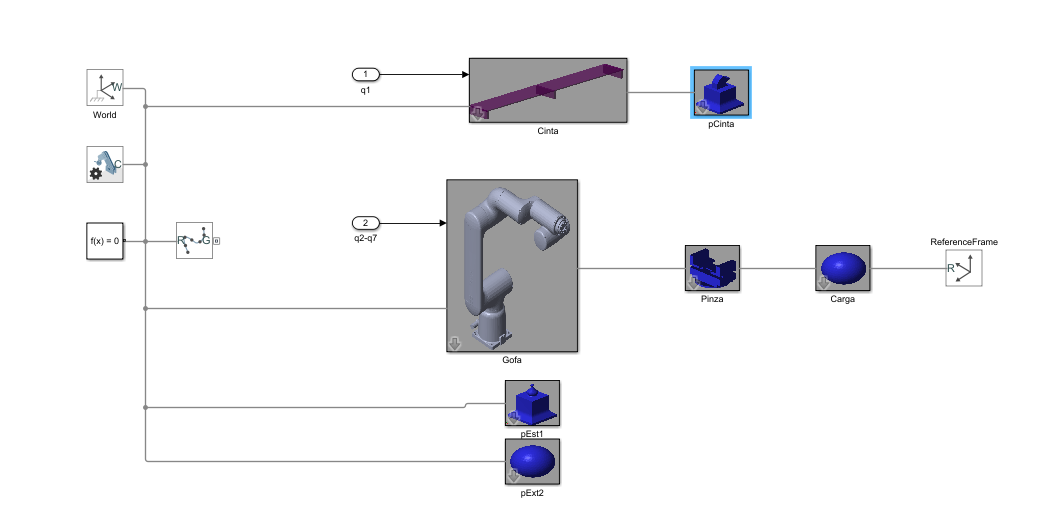

clear all
deg= pi/180;

deg= pi/180;
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
Estacion= 'C21S3_Cinta_Robot';
q0_= zeros(1,7);
pose_= randn(3,3)*1e-3;

% Posicion base de la cinta
baseCinta= [[0,0,0]*1e-3, [0,0,0]*deg];

% Posición de la base del robot
baseRobot= [[600,700,-150]*1e-3, [90,0,0]*deg];


% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);

% Icono variable asociado al robot
Carga= Pieza('Null');
Carga.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);


% Icono variable asociado a la cinta
pCinta= Pieza('Torre');
pCinta.Base([[0,0,0]*1e-3, [0,0,90]*deg]);
pCinta.Tcp([[0,0,50]*1e-3,[0,0,180]*deg]);
pCinta.Color([0.4,0,0.4,1]);

% Iconos variables
pExt1= Pieza('Null');
pExt1.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
pExt1.Color([0.4,0,0.4,0.7]);


--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02      prismatic            Body01(1)   Body03(3)  
   3        Body03        Joint03          fixed            Body02(2)   
   4        Body04        Joint04          fixed              Base(0)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08       revolute            Body07(7)   Body09(9)  
   9        Body09        Joint09       revolute            Body08(8)   Body10(10)  
  10        Body10        Joint10  

pExt2= Pieza('Null');
pExt2.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
pExt2.Color([0.4,0,0.4,0.7]);

open(Estacion)
robot= importrobot(Estacion);
robot.showdetails
TcpCinta= 'Body02';

Herramienta: Body02
Simulación. Ts= 0.100 m/s


TcpPinza= 'Body12';
TcpCarga= 'Body13';

q0= zeros(1,7);
q0_= q0;
% Se crea el robot con el TCP de la cinta
rob= Cin(robot, Estacion, TcpCinta, q0);



### 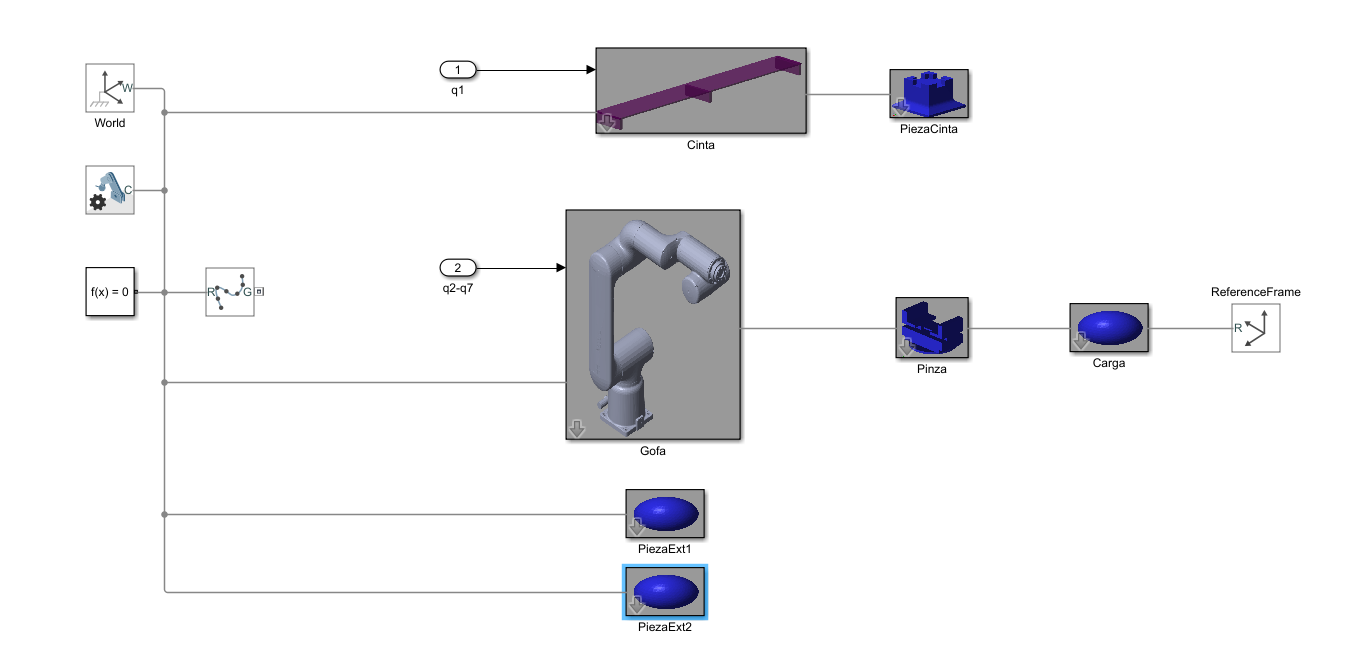

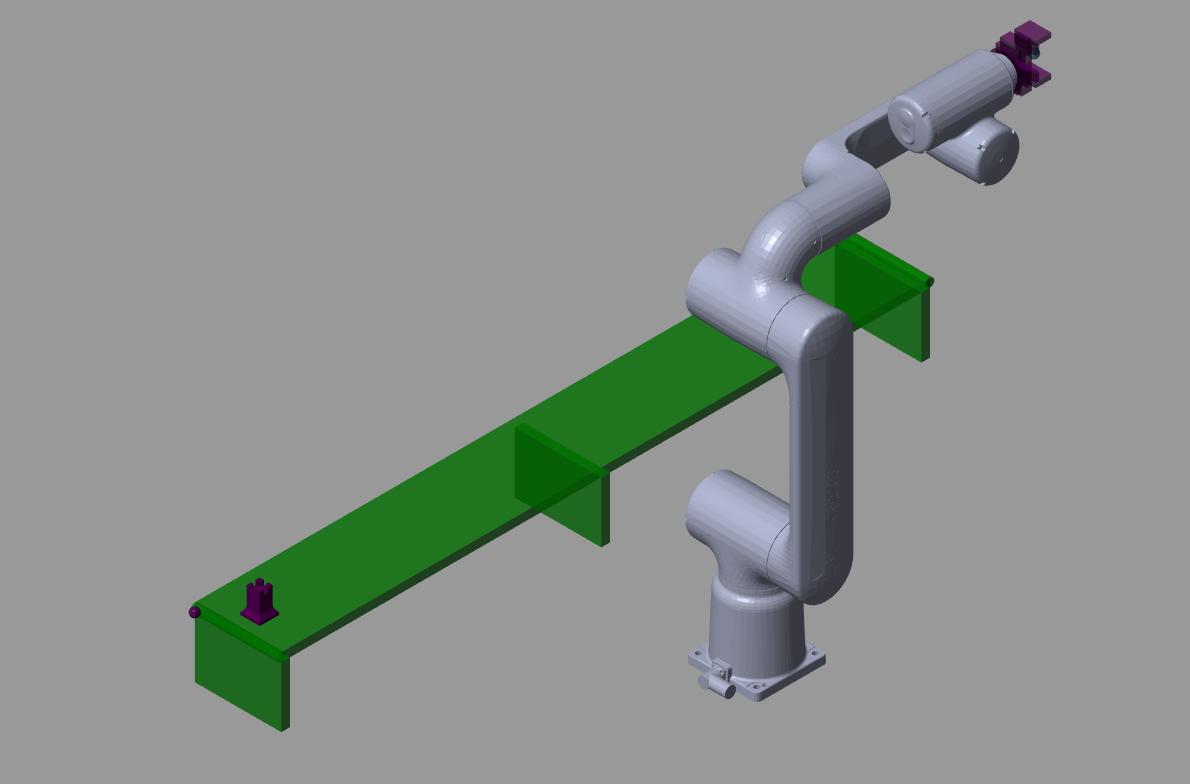

### Cambiar pieza en $pCinta$

pCinta= Pieza('Alfil');

pCinta.Base([[0,0,0]*1e-3, [0,0,90]*deg]);
pCinta.Color([1,0,0,1]);
rob.Show


### Mover cinta transportadora

- Se mueve el primer eje de la estación, que pertenece a la cinta.

% Se pone el TCP en la cinta

cinta =     0.1000    0.5500    0.0250         0         0   -1.5708


rob.Tool(TcpCinta);
q= zeros(1,7);
q(1)= 500e-3;
rob.MoveAbsJ(q);

% Posición del eje de la cinta
cinta= rob.Pose

### Cambiar TCP a la pinza del robot y mover robot a la $pCinta$

- Se cambia el TCP de la cinta a la pinza del robot.

- Cuando se calcula el movimiento se realiza con todos los ejes, pero el eje de la cinta no se mueve porque no ayuda en el objetivo, que es mover el TCP de la pinza.

% Se cambia de TCP, ahora es la pinza
rob.Tool(TcpPinza);
% El eje z es el prismatico de la cinta, y hacia abajo
% Ir a 50 mm por encima de la pieza de ajedrez
punto= [[0,-50,0]*1e-3,[0,0,-90]*deg];

rob.MoveJ(punto, cinta);

### Tomar la $pCinta$ en la *Carga*

- Se toma la pieza de la carga de la cinta a la carga del robot.

% Tomar la pieza y volve al origen en todos los ejes, incluido la cinta
% Pegar en Carga la PiezaCinta, carga está en rob y PiezaCinta en cinta

PegarEn(Carga, pCinta, rob, cinta)
% Ir al inicio en todos los ejes
eje= zeros(1,7);
rob.MoveAbsJ(eje);

### Mover robot a una posición dada y deja la pieza en p*Ext1*

- Se deja la pieza en $pExt1$, que pertenece al origen.

- Se ha elegido un punto que está encima de la cinta.

eje= zeros(1,7);
rob.MoveAbsJ(eje);

punto= [[100,1000,75]*1e-3, [0,0,180]*deg];
rob.MoveJ(punto);
PegarEn(pExt1,Carga,[],rob)
eje= zeros(1,7);
rob.MoveAbsJ(eje);


### Crea otra pieza en $pCinta$

- Se vuelve a crear otra pieza en la carga de la cinta.

pCinta= Pieza('Caballo');

pCinta.Base([[0,0,0]*1e-3, [0,0,90]*deg]);
pCinta.Color([0,0,0,1]);
rob.Show


### Repetir movimiento